# Analyse et Synthèse de signaux périodiques

**But : **Le but de ce laboratoire est d'expérimenter et vérifier la décomposition en série de Fourier d’un signal périodique ainsi que sa reconstruction à partir des coefficients de Fourier. L’application de cette technique est le calcul de la réponse d’un système linéaire (ou pas) à un signal périodique en entrée. Ce calcul peut s’avérer long ou impossible techniquement dans certains cas dans le domaine temporel par les équations aux différences ou par la convolution. Cette méthode se révèle être puissante et simple à mettre en oeuvre. Dans le domaine de l’optique d’ailleurs la mise en application du traitement du signal se fait uniquement dans le domaine fréquentiel.

clc; clear; close all;

## Rappel théorique

### Analyse fréquentielle par séries de Fourier d’un signal périodique

Comme on l’a vu dans l’analyse de Fourier, la décomposition d’un signal en une combinaison linéaire de fonction harmoniques (exponentielles complexes d’amplitude X(jk)) se fait à partir de la relation suivante :


$$X\left(\textrm{jk}\right)=\frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} x_T \left(t\right)\exp \left(-\textrm{j2}\pi \;{\textrm{kf}}_0 t\right)\textrm{dt}$$


Dans le cas d’un signal discret périodique l’intégrale est remplacée par une somme et la variable *t* est remplacée par *nTe* et donc *T* est remplacé par *NTe* ce qui a pour conséquence de faire disparaitre *Te* dans la somme :


$$X\left(\textrm{jk}\right)=\frac{1}{N}\sum_{n=-N/2}^{N/2} x_N \left({\textrm{nT}}_e \right)\exp \left(-\textrm{j2}\pi \;{\textrm{kf}}_0 nT_e \right)$$


Le  signal échantillonné  $x_N(nT_e)$  est  remplacé  avec  la  sequence (vecteur) discrete $x_N[n]$ et la  foction périodique complexe${w\left(kf_{0\;} ,{\textrm{nT}}_e \right)}^* =\exp \left(-\textrm{j2}\pi \;{\textrm{kf}}_0 nT_e \right)$ est  remplacé par le  vecteur  complexe  contenant les  N échantillons $w_k {\left\lbrack n\right\rbrack }^* =\exp \left(-\textrm{j2}\pi \;{\textrm{kf}}_0 nT_e \right)$

Cette opération est facile à réaliser avec un logiciel de calcul numérique, car il s’agit de calculer pour chaque coefficient k, le produit scalaire entre le vecteur signal $x_N \left\lbrack n\right\rbrack$sur une période et le vecteur de l’exponentielle complexe (son conjugué) sur le même nombre de points à la fréquence $f={\textrm{kf}}_0$.

$X\left\lbrack \textrm{jk}\right\rbrack =\frac{1}{N}\left\langle x_N \left\lbrack n\right\rbrack ,w_k \left\lbrack n\right\rbrack \right\rangle$= $\frac{1}{N}\sum_{n=-N/2}^{N/2} x_N \left\lbrack n\right\rbrack$$w_k {\left\lbrack n\right\rbrack }^*$

### Synthèse d’un signal périodique à partir des coefficients de la série de Fourier

Comme on l’a vu dans l’analyse de Fourier, la reconstruction ou synthèse d’un signal se fait à partir de ses k composantes spectrales *X[jk]*:


$$x_{\left(K\right)} \left(t\right)=\sum_{k=-K}^K X\left\lbrack \textrm{jk}\right\rbrack \exp \left(+\textrm{j2}\pi \;k\;f_0 t\right)$$


Il en va de même pour un signal discret :


$$x_{\left(K\right)} \left\lbrack n\right\rbrack =\left\langle X\left\lbrack \textrm{jk}\right\rbrack ,{w_k \left\lbrack n\right\rbrack }^* \right\rangle \;\;\;=\sum_{k=-K}^K X\left\lbrack \textrm{jk}\right\rbrack$$

$$w_k \left\lbrack n\right\rbrack$$


### Réponse fréquentielle d’un système LIT discret

Connaissant la fonction de transfert d’un système numérique dans le domaine de Z :


$$H\left(z\right)\equiv \frac{Y\left(z\right)}{X\left(z\right)}=\frac{b_0 +b_1 z^{-1} +b_2 z^{-2} }{1+a_1 z^{-1} +a_2 z^{-2} }$$


on peut facilement calculer sa réponse fréquentielle en remplaçant l’opérateur de retard $z^{-1}$ par sa transformée de Fourier $\exp \left(-j\Omega \right)$ où $\Omega$ est la pulsation normalisée et *f'* la fréquence normalisée :


$$\Omega \equiv 2\pi \;f^{\prime } =2\pi \;f\;T_e =2\pi \;\frac{f}{f_e }\;\;\;-\pi \;\le \Omega \le +\pi \;$$


On obtient alors la fonction de transfert harmonique $H\left(j\Omega \right)=H\left({\textrm{jf}}^{\prime } \right)$ :


$$H\left(j\Omega \right)\equiv \frac{Y\left(j\Omega \right)}{X\left(j\Omega \right)}=\frac{b_0 +b_1 e^{-j\Omega } +b_2 e^{-\textrm{j2}\Omega } }{1+a_1 e^{-j\Omega } +a_2 e^{-\textrm{j2}\Omega } }\;$$


La fonction de transfert harmonique $H\left(j\Omega \right)$est complexe. On peut représenter graphiquement cette fonction de différentes manières, une de celles ci est la représentation de Bode. On peut tracer en fonction de la fréquence normalisée f' ou de la pulsation normalisée $\Omega$ le module $\left|H\left(j\Omega \right)\right|$. On obtient ainsi le Bode d’amplitude qui indique le gain du système pour un signal d’entrée sinusoïdal de pulsation (d’où le nom de réponse harmonique). 

Si on trace l’argument du nombre complexe $H\left(j\Omega \right)$ en fonction de $\Omega$ on obtient le **Bode de phase** du système indiquant le déphasage que le système applique à un signal d’entrée sinusoïdal de pulsation $\Omega$.

Usuellement on utilise un axe logarithmique pour l’axe des fréquences normalisées, et un axe logarithmique pour l’axe du module $\left|H\left(j\Omega \right)\right|$ que l’on exprime en deci-Bell [dB] :


$${\left|H\left(j\Omega \right)\right|}_{\textrm{dB}} =20\log_{10} \left(\left|H\left(j\Omega \right)\right|\right)$$


## Travail demandé

### Analyse par série de Fourier d’un signal discret périodique (ex1)

Le travail qui est demandé dans cette section s’inspire directement du chapitre consacré à la décomposition en Série de Fourier et à la reconstruction à partir des coefficients de Fourier. 

La première tâche consiste à écrire une fonction Matlab qui permet de calculer les coefficients *X[jk]* à partir de une séquence d’échantillons sur la période du signal à analyser $x_N \left\lbrack n\right\rbrack$. Cette fonction aura l’entête suivant :

*Xjk* contient les **2M + 1** coefficients de Fourier (la composante continue **k=0 **et les **2M** harmoniques pour  **k = [-M ... + M]** ), calculées en utilisant la décomposition en série de Fourier et les échantillons **xT **=  $x_N \left\lbrack n\right\rbrack$, aux instants $t=n T_e$**= tT**. Notez  que  la  longueur  de $x_N \left\lbrack n\right\rbrack \;$ est une période  complète  de **N** échantillons, ce  qui  est un paramètre implicite.

Ensuite écrivez la fonction permettant l’opération inverse, la synthèse :

***Xjk*** contient les **2M +1** coefficients de Fourier (la composante continue et les **2M** harmoniques), ***f0*** est la fréquence fondamentale du signal périodique et **tt** le vecteur du temps indiquant les  instant d'échantillonnage et sur quelle durée vous voulez synthétiser le signal (il  se peut  que  cette  durée  represente un temps  supérieur  à la période  fodamentale **T0=1/f0** du signal périodique) .

Voici les opérations et analyses à réaliser :

- Ecrivez la fonction AnalySF

- Ecrivez la fonction SynthSF

- Chargez le fichier enregistré load(’enreg_signaux2.mat’); Dans l’espace de travail vous trouverez le signal à analyser ***xtt*** avec son vecteur du temps ***tt*****,** une période exacte de ce signal ***xT*** avec son vecteur de temps ***tT*** , la période ***T0*** et la période d’échantillonnage ***Te***.

- Tracez et observez le signal **x[n]** en entier ainsi que une période de celui ci ; Que valent sa puissance et ses valeurs moyenne et efficace?

- Calculez le vecteur **f[k]** des fréquences des harmoniques auxquelles se réfèrent les coefficients **X[jk]** du signal **x[n]** .

- Calculez les coefficients **X[jk] **avec la fonction **AnalySF()** en prenant **M=100** harmoniques. Vérifiez que la puissance calculée avec **X[jk]** soit proche du résultat que celle calculée avec **x[n]**.

- Prenez maintenant que les **M=10 **premier coefficients de Fourier et reconstruisez le signal **xr[n] **sur la même durée que le signal d’origine **x[n]**  avec la fonction **SynthSF** (a) que valent sa puissance et ses valeurs moyenne et efficace ? (b) que vaut la valeur efficace de l’erreur entre **x[n]** et **xr[n]** ?

- Affichez ces résultats comme sur la figure 1.

% votre code

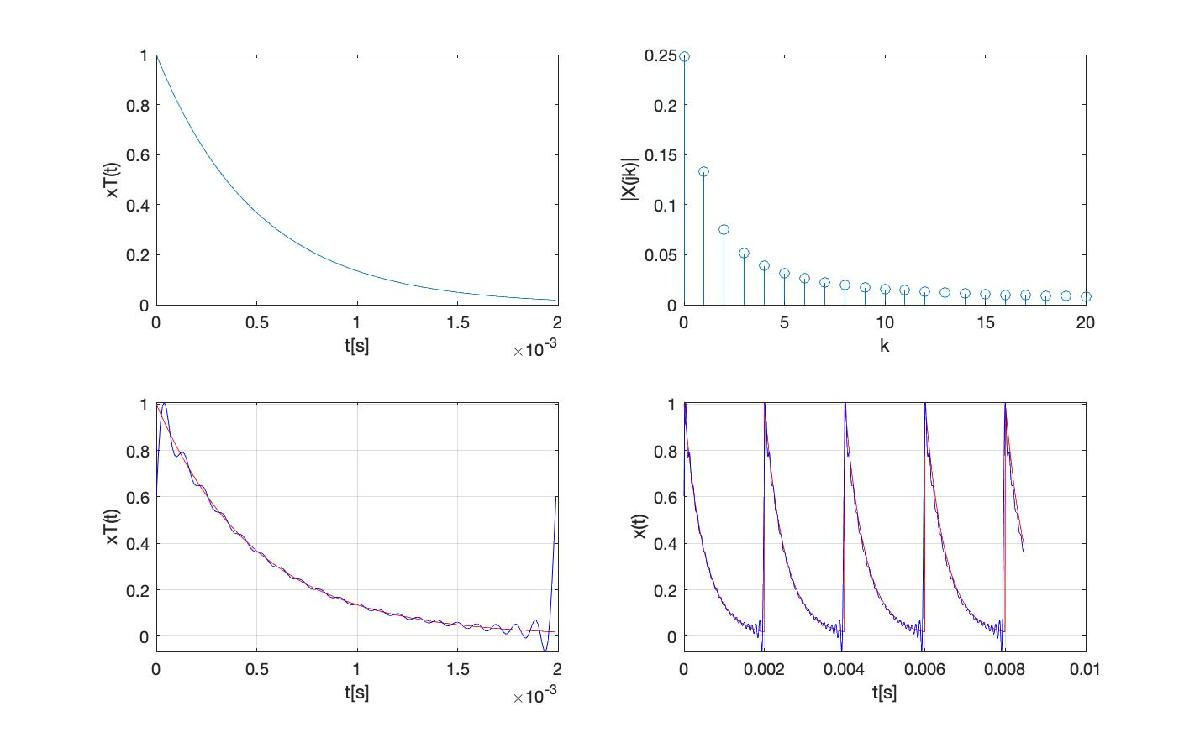

### Filtrage des harmoniques (ex2)

Le signal périodique sera appliqué à un filtre passe bas de type Butterworth du 4eme ordre dont les caractéristiques sont résumées si dessous. La fonction *butter* permet de créer le numérateur et le dénominateur du filtre :

Pour chaque fréquence harmonique de notre signal périodique il faut calculer l’atténuation et le déphasage introduit par le filtre. La fonction bode permet de calculer ces valeurs en fonction des fréquences qui nous intéressent, du spectre bilatéral  avec  **k = 0 : 2M+1** , ou unilatéral  avec  **ku = M+1 : 2M+1. **Par  consequent les  indexes  des vecteurs** Xjk[Ik]  **sont** Ik = 1:2M+1 **pour la version bilatérale  et** Iku = M+1 : 2*M+1 **pour la version unilatérale.

Affichez le bode du filtre comme dans la figure ci dessous :

% votre code

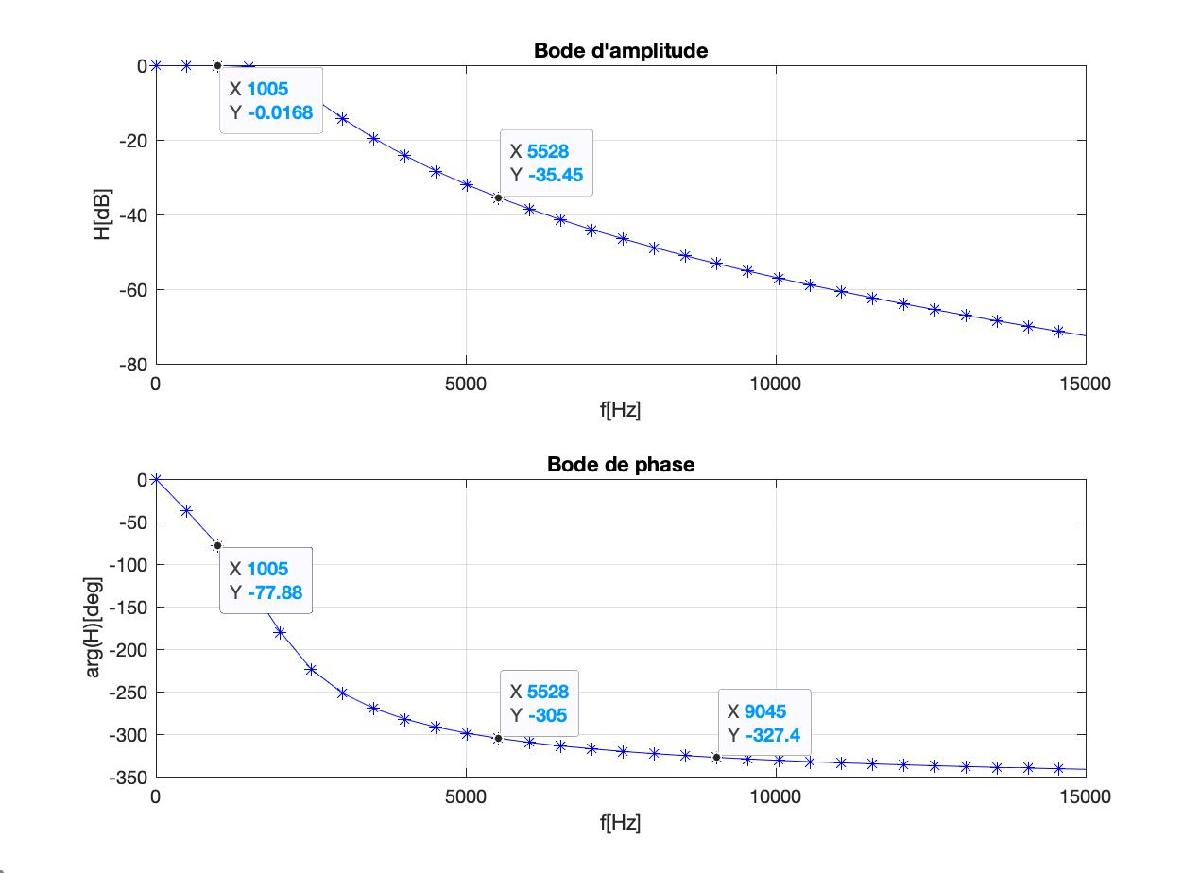

A ce point il ne reste plus qu’à multiplier chaque coefficient de Fourier par le module de H(fk) à la fréquence de l’harmonique considérée, et par une exponentielle complexe qui applique le déphasage

arg{H(fk)}. Donc les coefficients de Fourier du signal de sortie seront donnée par :


$$Y\left\lbrack \textrm{jk}\right\rbrack =X\left\lbrack \textrm{jk}\right\rbrack \cdot \left|H\left(f_k \right)\right|\cdot \exp \left(j\;\ldotp \;\arg \left\lbrace H\left(f_k \right)\right\rbrace \right)$$


Ce  calcul  se  fait pour  toutes les  harmoniques  k (positives et négatives). En Matlab cela se traduit par :

Remarquez que l’argument de H fourni par la fonction bode() est en degrés. Vous afficherez dans le même graphe les coefficients X(jk) et ceux du signal de sortie Y (jk) (un graphe pour le module et un graphe pour la phase comme montré dans les deux graphes du haut de la figure du bas).

Calculez Yjk[Ik] bilatéral  et la phase de Xjk  et  de Yjk  en utilisant la  fonction angle() appliqué à ces  vecteurs  complexes. Les  modules des  vecteurs  complexes  se  calculent  avec la  fonction abs().

% votre code

### Synthèse du signal à la sortie du filtre

A partir des coefficients Y [jk] calculés précédemment synthétisez le signal yR[n] en sortie du filtre à l’aide de la fonction SynthSF précédemment créée. Pour ceci prenez seulement les coefficients Y (jk) qui n’ont pas été atténuées plus que 40 [dB]. Déterminez donc le nombre d’harmoniques.

- Déterminez le nombre d'harmonique **M40 **qui ne sont pas atténués de plus de 40dB (utilisez la  variable précedemment calculée MagFkdB).

- Synthétisez le signal yR[n] à l'aide de la fonction SynthSF et des coefficients Y [jk] bilatéral, en utilisant le nombre d'harmonique déterminé (2*M40 + 1 valeurs)

- Que valent sa puissance et ses valeurs moyenne et efficace de yR[n] ?

- Comparez le signal yR[n] ainsi obtenu avec celui obtenu par le filtrage opéré par la fonction filter().

- Affichez les résultats comme dans la figure ci dessous, les   spectres  de  phase  et  d'amplitude  sont  unilatéraux.

% votre code